KPS_st.name='KPS'; 
KPS_st.lat=46.966;
KPS_st.lon=19.583;
KPS_st.alt=125;
KPS_st.env='con';
KPS_st.footp='RB';


KPS_rd=read_betsy('KPS_2006_2018',KPS_st.name);

datevec(KPS_rd.Time(1))

ans =         2006           5          10           0           0           0

datevec(KPS_rd.Time(end))

ans =         2018           1           1           0           0           0

prctile(KPS_rd.U_S,[5 50 95])

ans =    11.2500   23.5500   44.3500

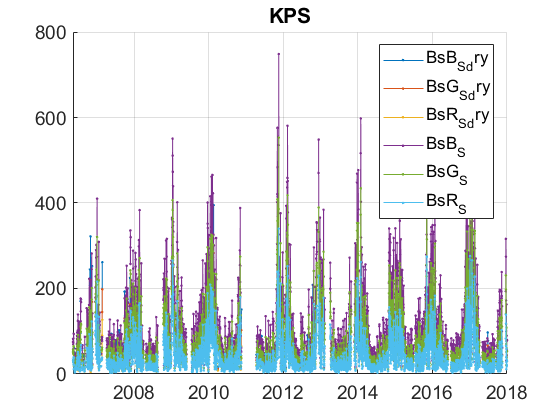

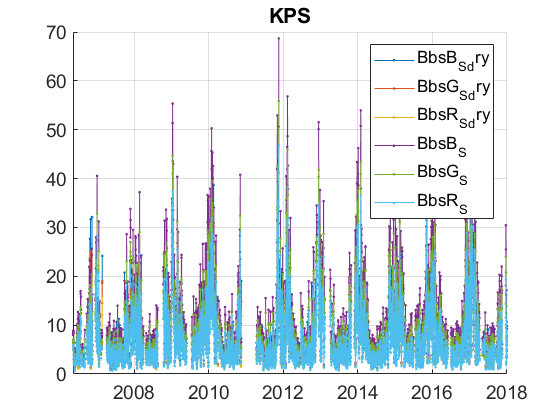

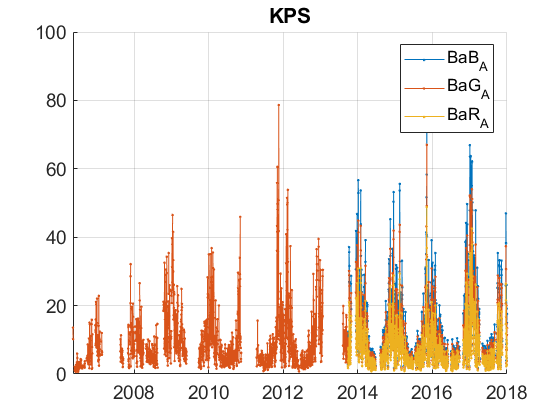

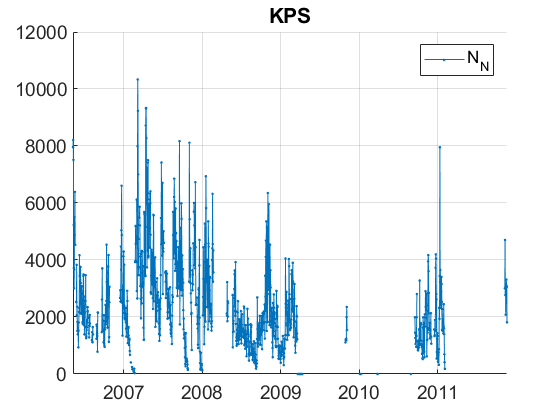

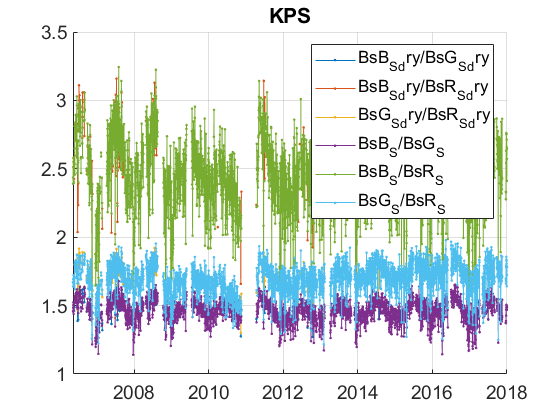

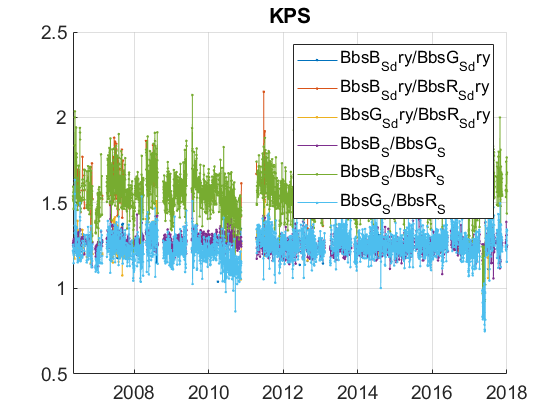

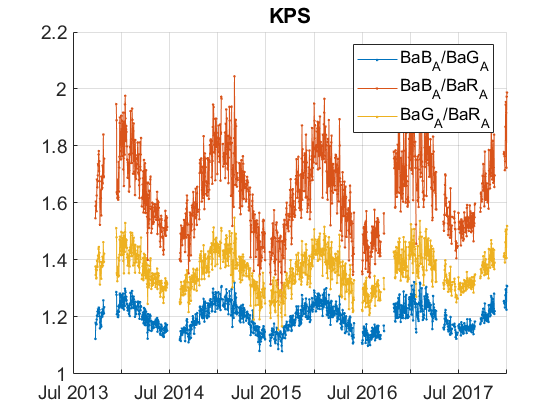

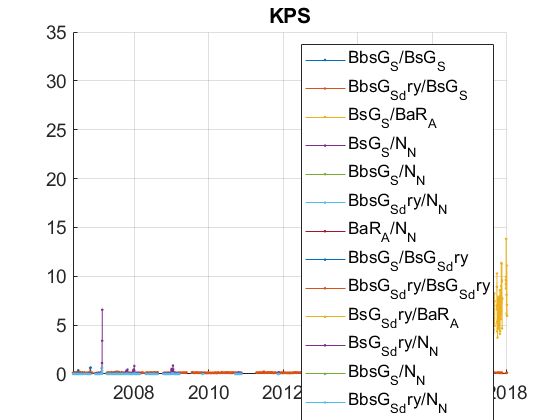

plotFigControl(KPS_rd,KPS_st.name);

% 1 size cut, ok
% sc: ok, max in winter, no negatives
% abs: 1 size cut, max in winter, no negatives
% abs: clear seasonal cycle of the exponent: max in winter (1.8, min 1 in summer)


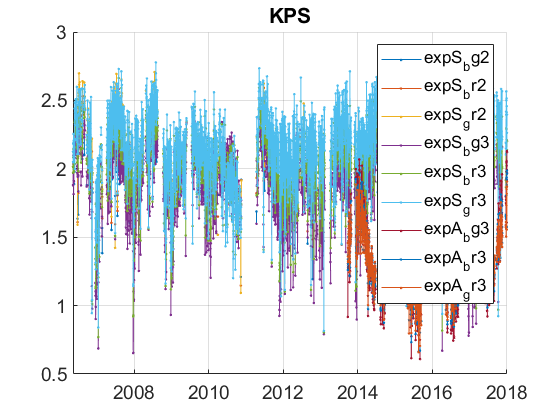

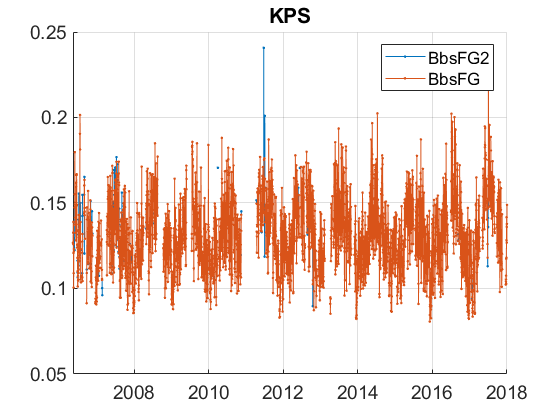

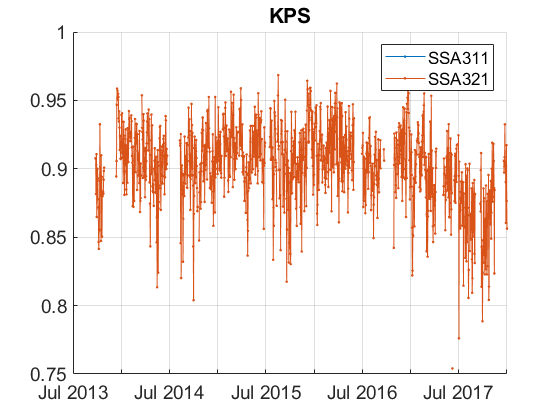

lambdaSC=[450;550;700]*ones(1,4);
lambdaAE=[467;530;660]*ones(1,4);
lambdaAE7=[370 470 520 590 660 880 950];
KPS_cal=compute_exp_SSA(KPS_rd,lambdaSC, lambdaAE);
plotFigControl_cal(KPS_cal, KPS_st.name);

%Questions:
%problems:
% sc: hole nov 2010-April 2011: real or databank problem ?
%BSP: April-Nov 2010: the ratio of the backscattering b/R and G/R is decreasing a lot. It seems to have recoved after the hole: modification of the red wavelength ?
%BSP: April 2017: the ratio of th backscattering B/R and G/R is too low. What happend ?
%What is strange is that it is not really visible in the scattering.

%abs: a lot of holes ( March-Aug 2007, Aug-Oct 2008, June-Sept 2009, Nov 2010 -Apr 2011, Feb-Jul 2013)
% are they real holes or databank problems ?
% the change PSAP 1w to CLAP does not seem to induce a rupture 


%N: a lot of holes, not possible to use for homogeneisation

KPS_tr=KPS_rd;
KPS_tr.y=year(KPS_tr.Time);
%enleve une valeur de 2018
KPS_tr=KPS_tr(1:end-1,:);
% begin at the beginning of a year: 2008 due to inlet change
% end 2017
P=timerange('2006-01-01','2008-01-01');
%not necessary to analysee dry since RH ok since feb 2008
KPS_tr.U_S11(P)=NaN;
prctile(KPS_tr.U_S11,[5 50 95])

ans =    10.7000   22.3000   36.9500

KPS_tr.U_S11=[];
names=fieldnames(KPS_tr);
c=endsWith(names,["dry";"3"]) | startsWith(names,["T1";"T0";"T_";"P_";"P1_";"P0_";"N"]);
N=names(c);
for i=1:length(N)
    KPS_tr.(N{i})=[];
end

%scatG: 2008-2017

KPS_tr.BsR_S11=[];
KPS_tr.BsB_S11(P)=NaN;
KPS_tr.BsG_S11(P)=NaN;
%Bsc: 2008-2017
KPS_tr.BbsB_S11=[];
KPS_tr.BbsR_S11=[];
KPS_tr.BbsG_S11(P)=NaN;
%BaG: 2008-2017
% do the SSA with green absorption in order to have the complete time series
%remove 10.5.2013 that was changed by Andràs
Px=timerange('2013-05-10','2013-05-11');
KPS_tr.BaG_A11(P)=NaN;
KPS_tr.BaG_A11(Px)=NaN;
KPS_tr.BaB_A11=[];
KPS_tr.BaR_A11=[];
%recalculate values
KPS_cal2=compute_exp_SSA(KPS_tr,lambdaSC, lambdaAE);
KPS_tr=outerjoin(KPS_tr, KPS_cal2);


% SSA seems to decrases after June 2017 (calibration or cleaning) Andras said not, but I'm not convinced
% is possible wait for 2018
KPS_result= all_trend_STN(KPS_tr,KPS_st); 

KPS_result_D=KPS_result(strcmp(KPS_result.parameter,'BsG_S11')==1 |strcmp(KPS_result.parameter,'BbsG_S11')==1 |strcmp(KPS_result.parameter,'BbsFG')==1 | strcmp(KPS_result.parameter,'BaG_A11')==1 |strcmp(KPS_result.parameter,'expS_bg1')==1|strcmp(KPS_result.parameter,'SSA311')==1,:);